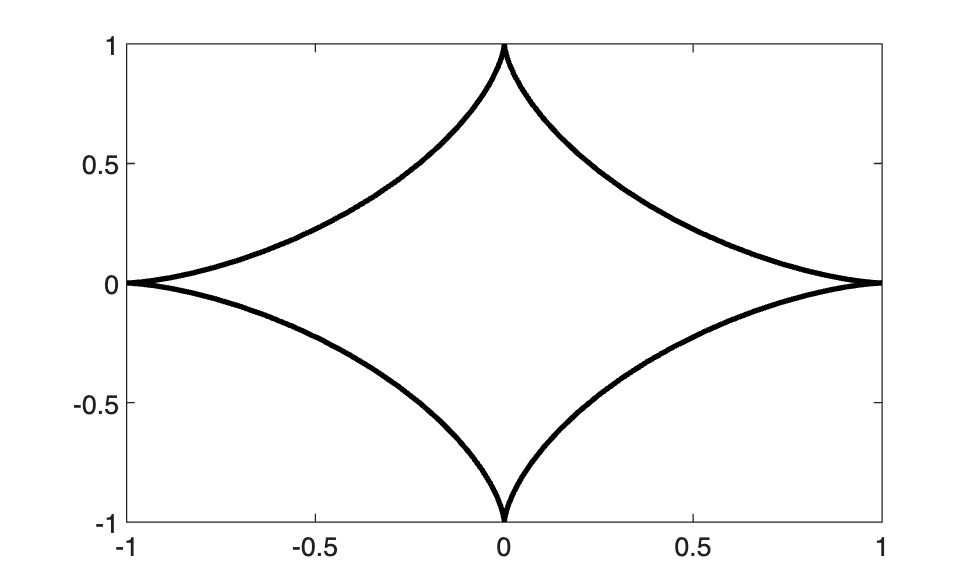

figure;
t=linspace(0,2*pi,100);
x=cos(t).^3;
y=sin(t).^3;
plot(x,y,'k', linewidth=2)

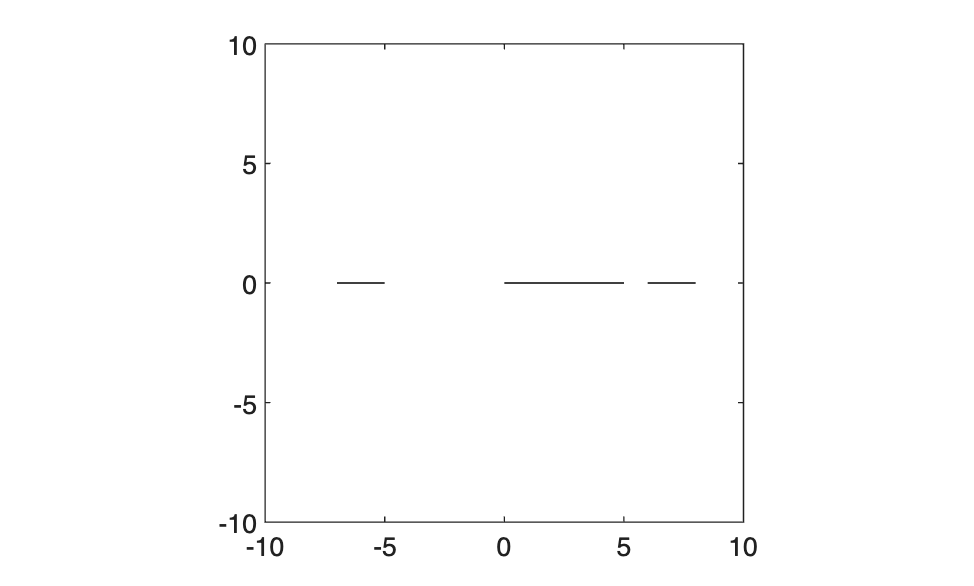

figure;
x = [-7 -5 inf 0 5 inf 6 8];
y = [0 0 0 0 0 0 0 0];
plot(x, y,'k')
axis equal
axis([-10 10 -10 10])

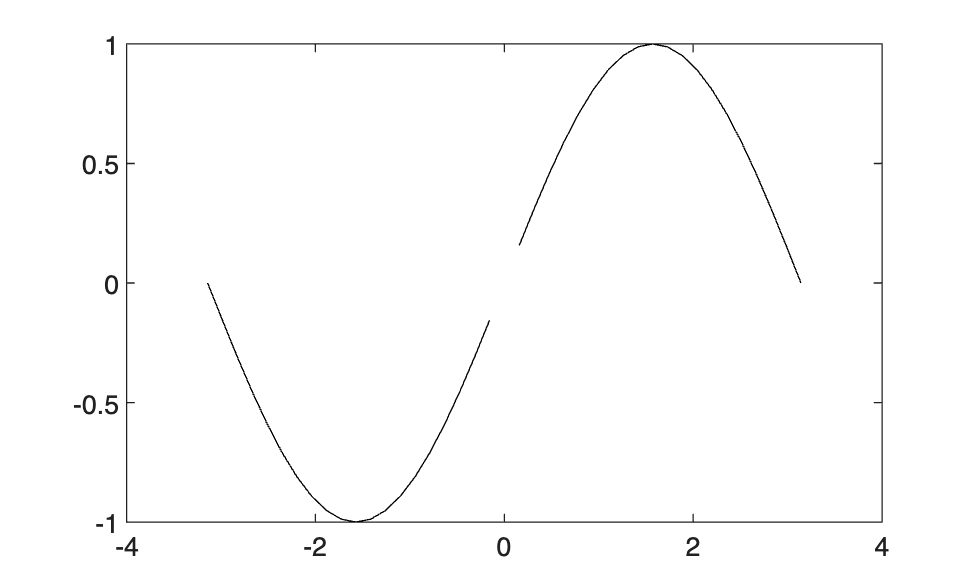


figure;
x=-pi:pi/20:pi;
y=sin(x);
i=find(x==0);
y(i)= inf;
plot(x,y,'k');

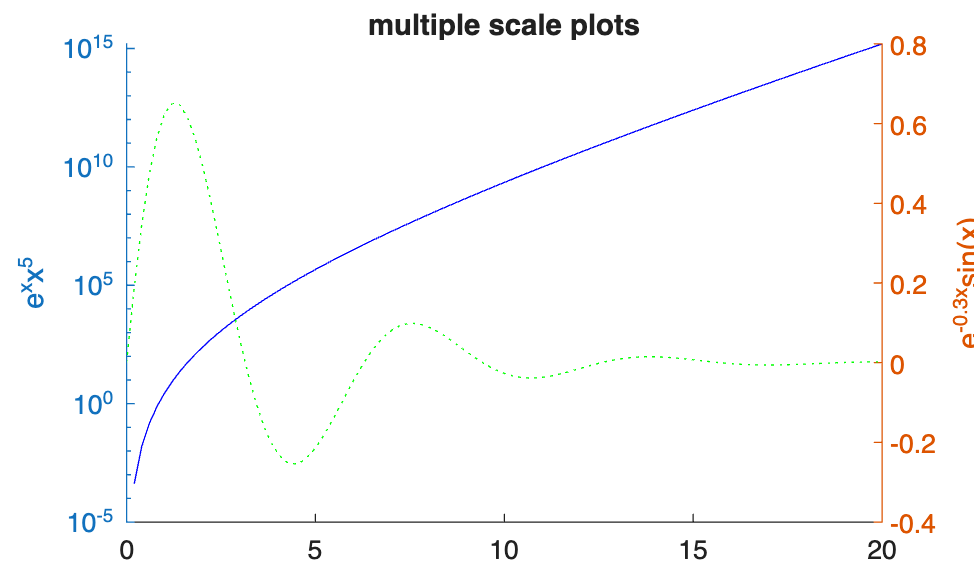

% 다중 스케일 
figure;
x=linspace(0,20,100);
y1=exp(x).*x.^5;
y2=exp(-0.3*x).*sin(x);
[ax,h1,h2]=plotyy(x,y1,x,y2, 'semilogy','plot');

set(h1, linestyle='-', color='b');
set(h2, linestyle=':', color='g');

set(get(ax(1),'ylabel'), 'string','e^xx^5');
set(get(ax(2),'ylabel'), 'string','e^{-0.3x}sin(x)');
title('multiple scale plots')

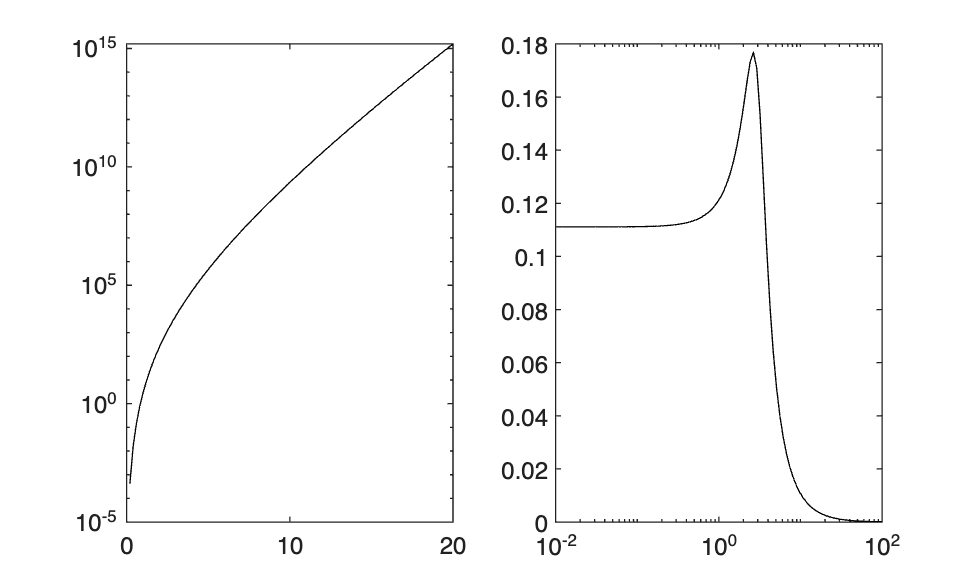

% log scale plot
figure;
subplot 121
x=linspace(0,20,100);
y=exp(x).*x.^5;
semilogy(x,y,'k');

subplot 122
w=logspace(-2,2,100);
gw=1./sqrt((9-w.^2).^2+4*w.^2);
semilogx(w,gw,'k');

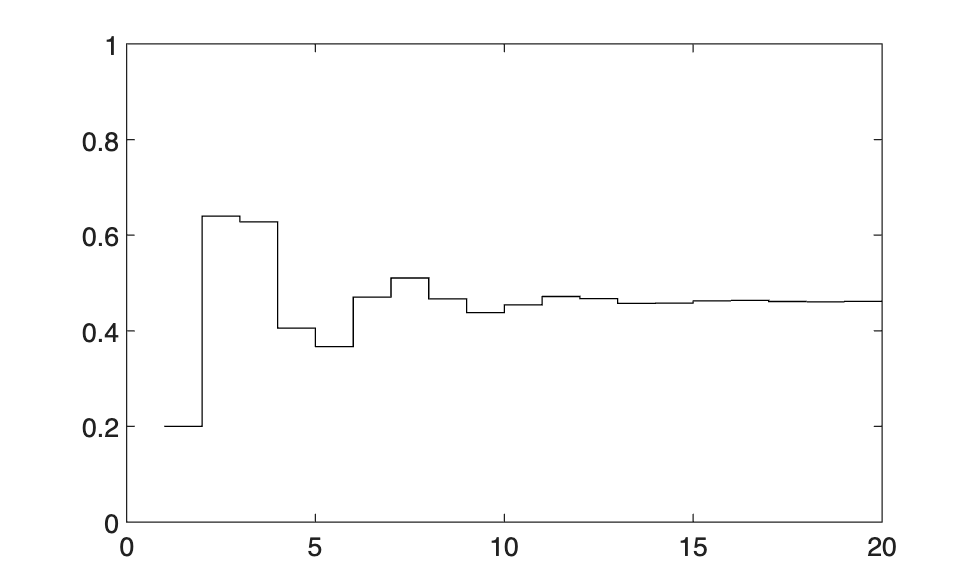

figure;
a=[1 -0.2 0.5]; b=[0.2 0.4];
u=ones(20,1);
y=filter(b,a,u);
stairs(y,'k');
axis([0 20 0 1]);

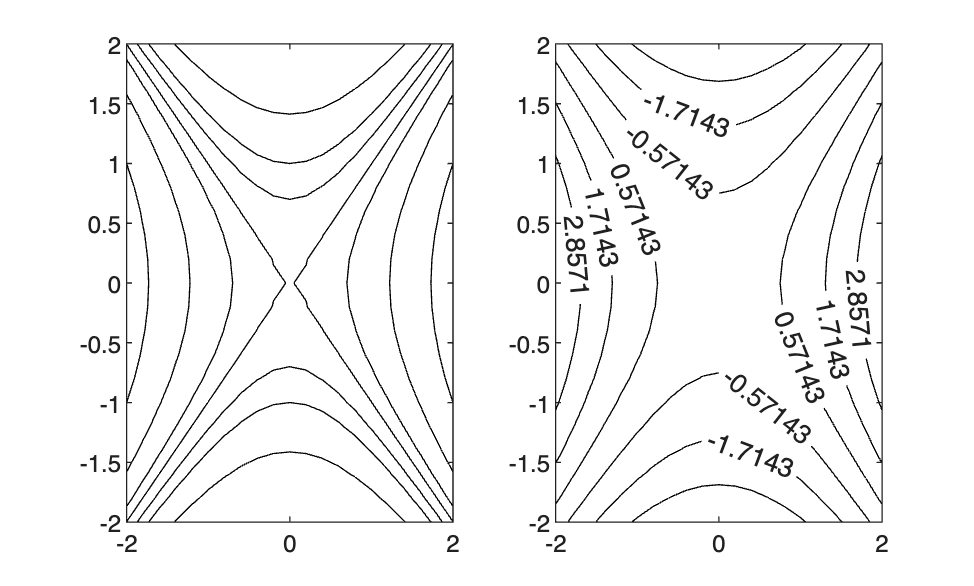


figure;
x=-2:0.2:2; y=x;
[X,Y]=meshgrid(x,y);
Z=X.^2-Y.^2;
subplot 121
contour(X,Y,Z, [-2 -1 -0.5 0.01 .5 1.5 3],'k');

subplot 122
[C,h] = contour(X,Y,Z,6,'k');
clabel(C,h,'labelspacing', 165)

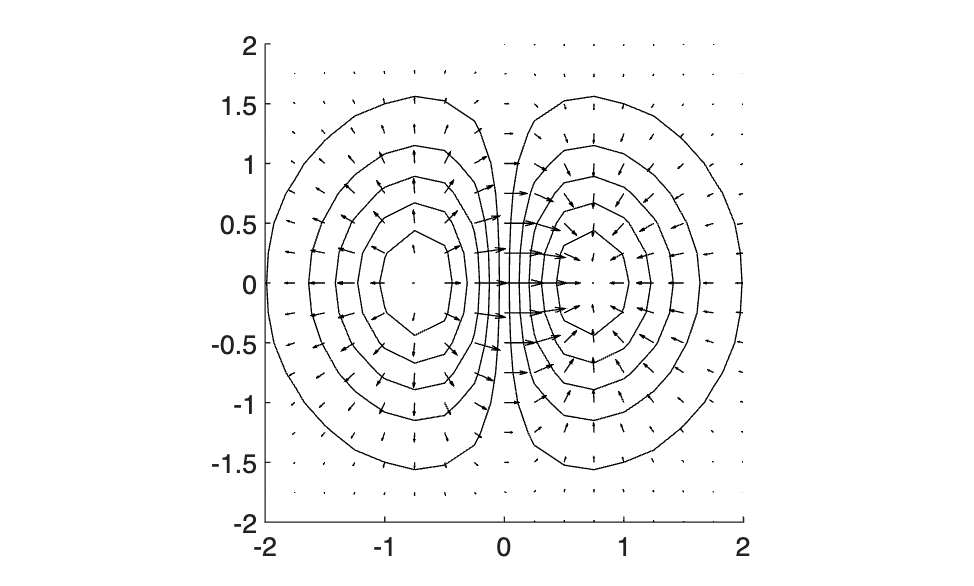

clf
figure;hold on;
dx=0.25; dy=0.25;
x=-2:dx:2; y=x;
[X,Y]=meshgrid(x,y);
Z=X.*exp(-X.^2-Y.^2);
[PX,PY]=gradient(Z,dx,dy); % Z의 구배를 반환함.

contour(X,Y,Z,10,'k');
quiver(x,y,PX,PY,1,'k');
axis equal
axis([-2 2 -2 2])

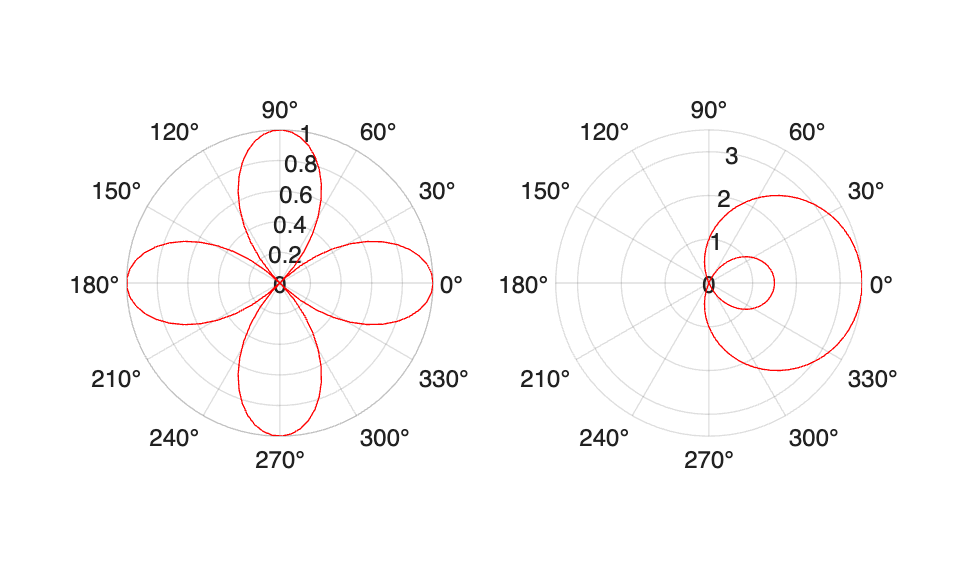

figure;
subplot 121
th=linspace(0,2*pi,100);
r=cos(2*th);
polarplot(th,r,'r');
subplot 122
r=1+2.5*cos(th);
polarplot(th,r,'r');